# **Domain**

Domain object

#### **1. Basic domains**

**Square**

domain = Domain('square',3);
domain.disp;

Domain object
Nodes (4):
     0     0
     3     0
     3     3
     0     3

Edges (4):
edge 1: from 1 to 2 straight
edge 2: from 2 to 3 straight
edge 3: from 3 to 4 straight
edge 4: from 4 to 1 straight
 


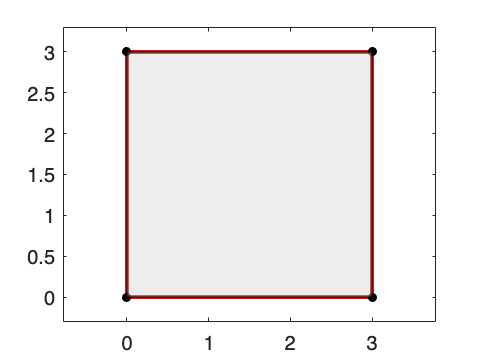

domain.plot;

**Disc**

domain = Domain('disc',3);
domain.disp;

Domain object
Nodes (1):
     3     0

Edges (1):
edge 1: from 1 to 1 param
 


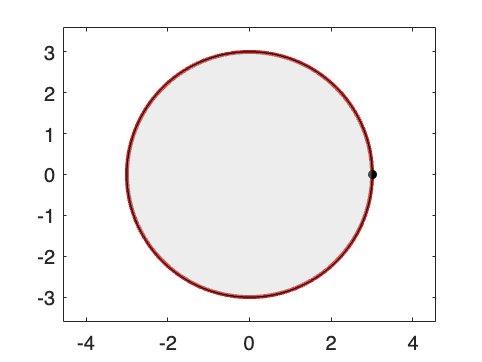

domain.plot;

**Polygon**

Simply gives the nodes  Nx2 matrix in trigonometric order.

nodes = [0 0; 2 0; 2 1;1 1;1 2;0 2];
domain = Domain(nodes);
domain.disp;

Domain object
Nodes (6):
     0     0
     2     0
     2     1
     1     1
     1     2
     0     2

Edges (6):
edge 1: from 1 to 2 straight
edge 2: from 2 to 3 straight
edge 3: from 3 to 4 straight
edge 4: from 4 to 5 straight
edge 5: from 5 to 6 straight
edge 6: from 6 to 1 straight
 


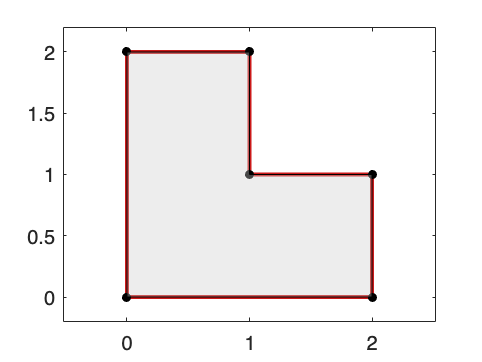

domain.plot;

You can make the edges and/or nodes numbering appear on the plot:

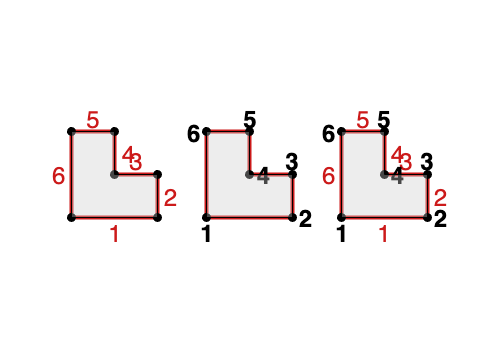

subplot 131
domain.plot('edgelabels');
axis off

subplot 132
domain.plot('nodelabels');
axis off

subplot 133
domain.plot('labels');
axis off
hold off

#### **2. Domains with curved edges**

You may use a parametric description of each curved edge using either a handle function of some expressions defining the parametric curve$t\mapsto \left(x\left(t\right),y\left(t\right)\right)$ depending on the parameter t . Always give the curve in trigonometric sense. 

**Half-disc**

Define first some nodes as usual:

nodes = [-1 0; 1 0];

Then define the edges as cells:

f = @(t) [cos(t) sin(t)];

edge1 = {1,2}; % A straight edge
edge2 = {2,1,f,[0 pi]}; % A curved edge
edges = {edge1,edge2};

paying attention that the starting and ending points of the parametric curve match the indicated nodes. Then build the domain:

domain = Domain(nodes,edges);
domain.disp;

Domain object
Nodes (2):
    -1     0
     1     0

Edges (2):
edge 1: from 1 to 2 straight
edge 2: from 2 to 1 param
 


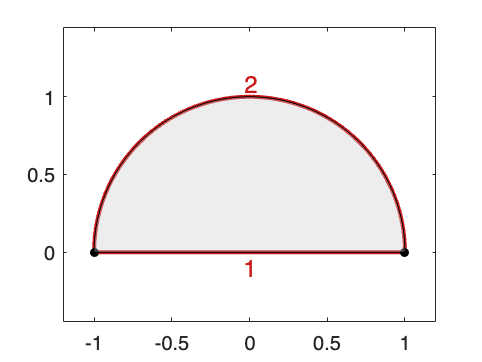

figure;
domain.plot('edgelabels');

**Parabolic domain**

You can also use expressions depending on the parameter t. 

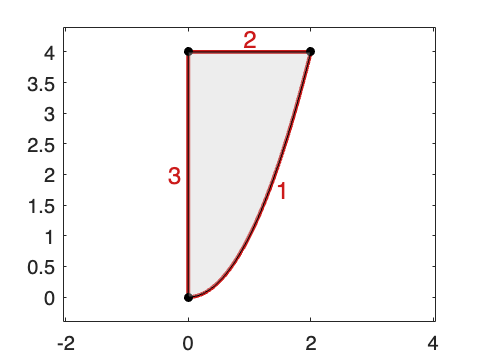

nodes = [0 0; 2 4;0 4];

edge1 = {1,2,{'t','t.^2'},[0,2]};
edge2 = {2,3};
edge3 = {3,1};
edges = {edge1,edge2,edge3};

domain = Domain(nodes,edges);

domain.plot('edgelabels');

**Singular domains**

Outer singularity

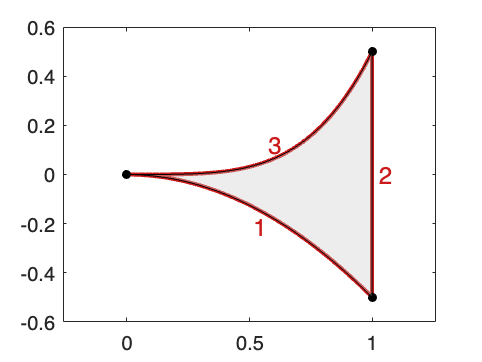

nodes = [0 0; 1 -1/2; 1 1/2];

edges = {{1,2,'t','-t.^2/2',[0,1]}
         {2,3}
         {3,1,'t','t.^4/2',[1,0]}};

domain = Domain(nodes,edges);

domain.plot('edgelabels');

Inner singularity

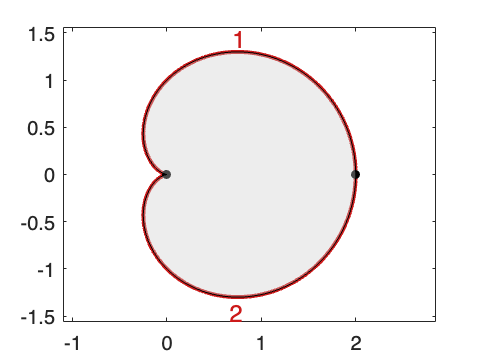

nodes = [2 0 ; 0 0];

edge1 = {1,2,'cos(t).*(1+cos(t))', 'sin(t).*(1+cos(t))',[0 pi]};
edge2 = {2,1,'cos(t).*(1+cos(t))', 'sin(t).*(1+cos(t))',[pi 2*pi]};

domain = Domain(nodes,{edge1,edge2});

domain.plot('edgelabels');

**Curved edges from intermediate edge nodes**

You can also define a curved edge using intermetiate edge nodes:

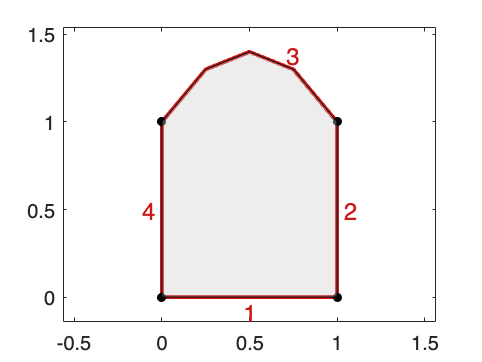

nodes = [0 0 ; 1 0 ; 1 1 ; 0 1];

enodes = [1 1; 0.75 1.3; 0.5 1.4; 0.25 1.3; 0 1];
edges = {{1,2};{2,3};{3,4,enodes};{4,1}};

domain = Domain(nodes,edges);

domain.plot('edgelabels');

#### **3. Domain with holes**

In order to create holes, you should add hole edges (straight or curved) in the trigonometric sense specifying that the domain is at its right side using the char parameter 'r' or 'R';

**Square domain with a circular hole**

nodes = [-1 -1; 1 -1 ; 1 1; -1 1;0.5 0];

edges = {{1,2}
         {2,3}
         {3,4}
         {4,1}
         {5,5,'0.5*cos(t)','0.5*sin(t)',[0,2*pi],'r'}};

domain = Domain(nodes,edges);

domain.disp;

Domain object
Nodes (5):
   -1.0000   -1.0000
    1.0000   -1.0000
    1.0000    1.0000
   -1.0000    1.0000
    0.5000         0

Edges (5):
edge 1: from 1 to 2 straight
edge 2: from 2 to 3 straight
edge 3: from 3 to 4 straight
edge 4: from 4 to 1 straight
edge 5: from 5 to 5 param, hole
 


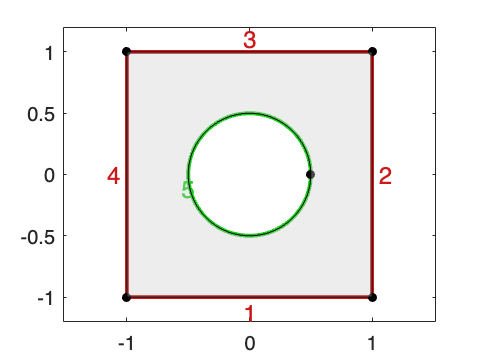

domain.plot('edgelabels');

**Circular domain with a singular hole**

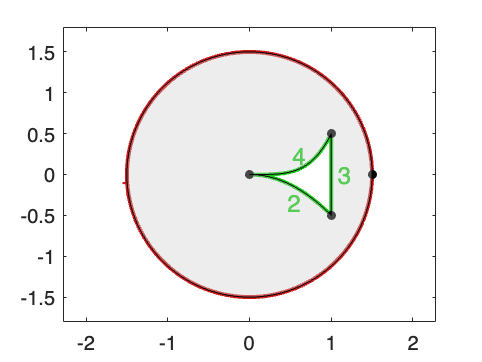

nodes = [1.5 0;0 0; 1 -1/2; 1 1/2];

edges = {{1,1,'1.5*cos(t)','1.5*sin(t)',[0,2*pi]}
         {2,3,'t','-t.^2/2',[0,1],'R'}
         {3,4,'r'}
         {4,2,'t','t.^4/2',[1,0],'R'}};

domain = Domain(nodes,edges);

domain.plot('edgelabels');

#### **4. Domain with inclusions and internal edges**

Similar to holes but we want now that the interior of the holes sto tay part of the domain. You just need to specify that the domain is both sides of the edges using the char parameter 'lr' or 'LR'. This kind of geometry will be used to generete a mesh inside and outside the inclusion. 

**Square with disc inclusion**

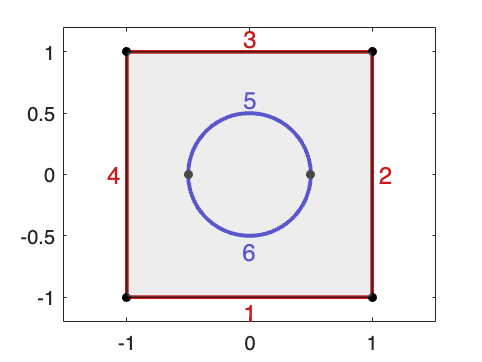

nodes = [-1 -1; 1 -1 ; 1 1; -1 1;0.5 0 ; -0.5 0];

edges = {{1,2}
         {2,3}
         {3,4}
         {4,1}
         {5,6,'0.5*cos(t)','0.5*sin(t)',[0,pi],'lr'}
         {6,5,'0.5*cos(t)','0.5*sin(t)',[pi,2*pi],'lr'}};

domain = Domain(nodes,edges);

domain.plot('edgelabels');

**Disc with cusp inclusion**

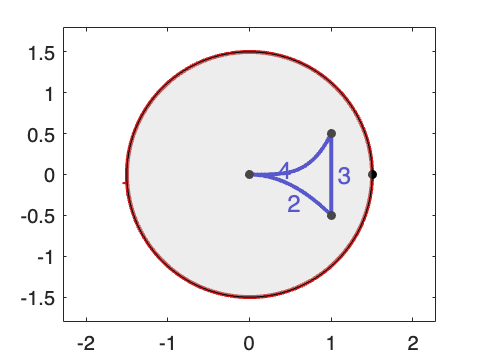

nodes = [1.5 0;0 0; 1 -1/2; 1 1/2];
edges = {{1,1,'1.5*cos(t)','1.5*sin(t)',[0,2*pi]}
         {2,3,'t','-t.^2/2',[0,1],'lr'}
         {3,4,'lr'}
         {4,1,'t','t.^4/2',[0,1],'lr'}};

domain = Domain(nodes,edges);

domain.plot('edgelabels');

**Rectangle with internal egdges**

nodes = [-3 -1;3 -1;3 1;-3 1;-2,-1;-2,1;2,-1;2,1];
edges = {{1,2},{2,3},{3,4},{4,1},{5,6,'lr'},{7,8,'lr'}};

domain = Domain(nodes,edges);

domain.disp;

Domain object
Nodes (8):
    -3    -1
     3    -1
     3     1
    -3     1
    -2    -1
    -2     1
     2    -1
     2     1

Edges (6):
edge 1: from 1 to 2 straight
edge 2: from 2 to 3 straight
edge 3: from 3 to 4 straight
edge 4: from 4 to 1 straight
edge 5: from 5 to 6 straight, internal
edge 6: from 7 to 8 straight, internal
 


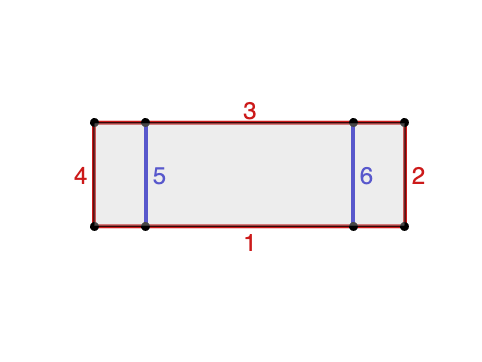

domain.plot('edgelabels');
axis off;

#### 5. Domain from a binary image

It is also possible to create a domain from a binary image. Create first a image matrix which values one inside the domain and zero outside. For exemple:

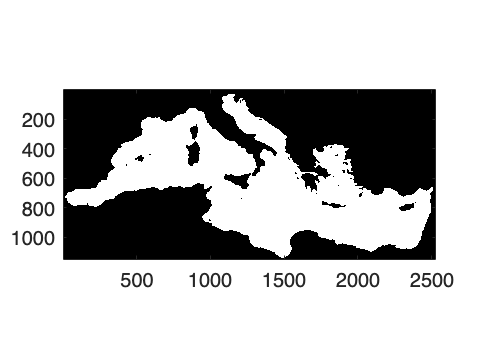

I = double(imread('mediteranee.png'));
I = sum(I,3)/3;
I(I>0) = 1;

imagesc(I);
axis image; colormap gray;

Then create the domain object:

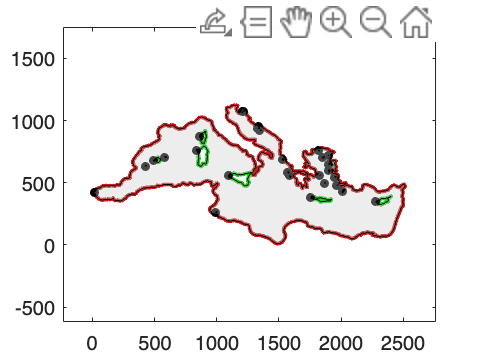

domain = Domain('image',I);

domain.plot;

Note that the constructor slighlty smooth the boundaries to a resolution of ~5 pixels and kills the smallest details. Undock the figure to see the domain details. 

Note also that you can fix the scale using a parameter dx that cooresponds to the pixel size of the image:

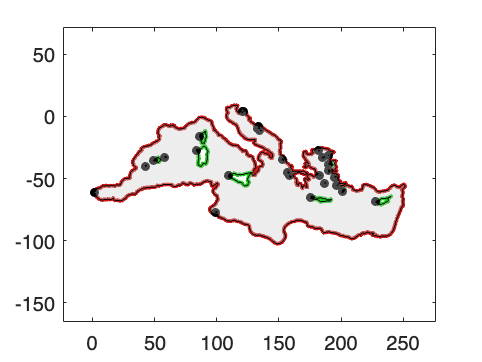

dx = 0.1;
domain = Domain('image',I,dx);

domain.plot;